Read test images.

img_lenna=imread("Lenna.jpg");

Inner function implementation.

% I1 = impyramid(img_lenna, 'reduce');
% I2 = impyramid(I1, 'reduce');
% I3 = impyramid(I2, 'reduce');
% figure, imshow(img_lenna)
% figure, imshow(I1)
% figure, imshow(I2)
% figure, imshow(I3)

Generate the image pyramid.

[g_pyramid,l_pyramid]=generate_pyramids(img_lenna)

g_pyramid = 7×1 cell 数组
    {512×512×3 uint8}
    {256×256×3 uint8}
    {128×128×3 uint8}
    { 64×64×3  uint8}
    { 32×32×3  uint8}
    { 16×16×3  uint8}
    {  8×8×3   uint8}


l_pyramid = 7×1 cell 数组
    {512×512×3 uint8}
    {256×256×3 uint8}
    {128×128×3 uint8}
    { 64×64×3  uint8}
    { 32×32×3  uint8}
    { 16×16×3  uint8}
    {  8×8×3   uint8}


    0.0004    0.5500    0.1429    0.4500

    0.1436    0.5500    0.1429    0.4500

    0.2868    0.5500    0.1429    0.4500

    0.4301    0.5500    0.1429    0.4500

    0.5733    0.5500    0.1429    0.4500

    0.7165    0.5500    0.1429    0.4500

    0.8597    0.5500    0.1429    0.4500



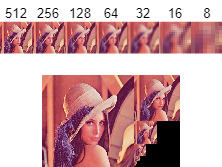

g_pyramid_concat=concatenate_image_pyramid(g_pyramid,2);
l_pyramid_concat=concatenate_image_pyramid(l_pyramid,2);
% figure,imshow(g_pyramid_concat)
% figure,imshow(l_pyramid_concat)
display_image_pyramid(g_pyramid,2)

Implement the functions manually.

function [g_pyramid,l_pyramid]=generate_pyramids(img)
    [m,n,c]=size(img);
    max_n=log2(m)-3;
    g_pyramid={img};
    for i=1:max_n
        gaussian_kernel = fspecial('gaussian', [5 5], 2);
        img_blur=imfilter(img,gaussian_kernel,"replicate","same","conv");
        l_pyramid(i,:)={img-img_blur};
        img=imresize(img_blur,0.5,"nearest");
        g_pyramid(i+1,:)={img};
    end
    l_pyramid(max_n+1,:)={img};
end

function display_image_pyramid(imgs,margin)

    N=size(imgs,1);
    
    canvas=concatenate_image_pyramid(imgs,margin);
    cw=size(canvas,2);
    margin=margin/N/cw;
    pm=margin;
    figure;
    for i=1:N
        disp([pm 0.55 1/N 0.45])
        subplot('Position', [pm 0.55 1/N 0.45]);
        imshow(imgs{i}); % 调整显示范围
        title(size(imgs{i}, 1))
        pm=pm+1/N+margin;
    end
    subplot('Position',[margin margin 1-margin 0.55-margin]);
    imshow(canvas);

end

function canvas=concatenate_image_pyramid(imgs,margin)

    [m,n,c]=size(imgs{1});
    canvas=zeros([m ceil(n*1.5+margin) c],"uint8");
    canvas(1:m,1:n,1:c)=imgs{1};

    pm=1;
    pn=n+1+margin;
    for i=2:size(imgs,1)
        [m,n,c]=size(imgs{i});
        canvas(pm:pm+m-1,pn:pn+n-1,1:c)=imgs{i};
        pm=pm+m;
    end

end



